close all, clear all, clc

## **HW03, 04**

Given,

P_o = 7.15;         % outlet pressure; MPa
T_av= 284.9;        % Avg temp; dC
m_fl = 20.3;       % mass inflow; t/hr
z = [0.210, 0.466, 0.7220, 0.9780, 1.49, 2.002, 3.026, 3.7080];  % axial positions; m

We additionally assume

wd = 132.5;         % assembly width; mm
rd = 8.0;           % assembly radius; mm
cf = 1.0;           % friction coeff
ksp = 1.2;          % spacer-grid p-loss factor

Also given, experimental pressure drop

DP_ze = [0.30, 0.39, 0.74, 0.84, 1.31, 1.77, 2.64, 3.12];   % KPa

And

n = 50;         % no. of experimental replication
CL = 95;        % level of confidence
sg_Ee = 0.03    % STD of 'Uncertainty' of experimental data; KPa 

sg_Ee = 0.0300

As we know


$$\bar{\;E_i } \left(z\right)=\mu_m -y_{\textrm{ei}} \left(z\right)$$


 $\bar{\;E_i } \left(z\right)$ = uncertainty of measurement at ith iteration, at position z of measurement $y_{\textrm{ei}}$

  $\mu_m$ = mean SRQ achieved from model

As, $\mu_m$ from the model is constant here, so, for n number of measurements, the STD of the experimental data will be equal to STD of its uncertainty  $\bar{\;E} \left(z\right)$. So-

sg_e = 0.03    % STD of experimental data; KPa 

sg_e = 0.0300

And the DP_ze values represents the mean of experimental data at each z position. 

Now, from the given model we can find the distribution of pressure drop along z

DP_z = bfbt_ax(P_o, T_av, m_fl, wd, rd, cf, ksp)        % axial P-drop; KPa

DP_z =     0.3616    0.4523    0.8302    0.9210    1.3896    1.8583    2.7955    3.3245


### HW04, 4.1

So, the estimated error along the axial line becomes-

E_b_z = DP_z - DP_ze        % estimated error along z-axis; KPa

E_b_z =     0.0616    0.0623    0.0902    0.0810    0.0796    0.0883    0.1555    0.2045


    (Ans)

Let's plot it against z positions

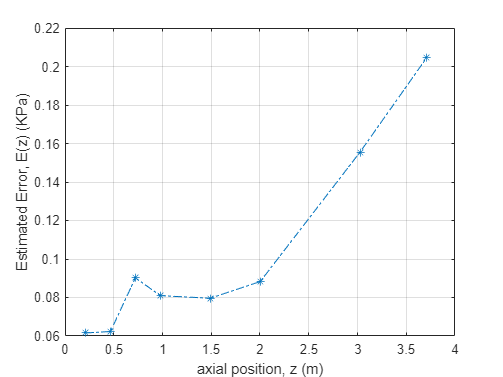

figure(1)
plot(z, E_b_z, '-.*'), grid on
xlabel('axial position, z (m)')
ylabel('Estimated Error, E(z) (KPa)')

### HW04, 4.2

And the STD of estimated error would be-

sg_z = std_ud(E_b_z)           % STD, estimated error; KPa

sg_z = 0.0505

    (Ans)

 The description of this user-defined STD function is given at the end of the section named **Functions**

### HW04, 4.3

We know,


$$\tilde{E} \left(z\right)-t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } \left(x\right)}{\;\sqrt{N}}<E\left(z\right)<\tilde{E} \left(z\right)+t_{\frac{a}{2},\nu \;} \frac{\bar{\sigma_e } \left(x\right)}{\;\sqrt{N}}\;$$


So, here,

a = 1 - CL/100

a = 0.0500

nu = n - 1 

nu = 49

sg_e_t = sg_e/sqrt(n)      % defining STD for t-distribution

sg_e_t = 0.0042

So, it becomes-


$$\tilde{E} \left(z\right)-t_{0\ldotp 025,\;\nu \;\;} \bar{\sigma_t } <E\left(z\right)<\tilde{E} \left(z\right)+t_{0\ldotp 025,\;\nu \;} \bar{\sigma_t } \;$$


Now, fromt the t-table score, we find, for $\nu =49;\frac{\alpha }{2}=0\ldotp 025$, t-value to be-

Let's interpolate

nu_x = [40, 50]; t_y = [2.021, 2.009];
t = interp1(nu_x, t_y, nu)

t = 2.0102

Then, let's find the error intervals along z-axis

E_b_z_up = E_b_z + t*sg_e_t        % upper bound; KPa

E_b_z_up =     0.0701    0.0709    0.0987    0.0895    0.0881    0.0968    0.1641    0.2130


E_b_z_lw = E_b_z - t*sg_e_t        % lower bound; KPa

E_b_z_lw =     0.0530    0.0538    0.0817    0.0724    0.0711    0.0797    0.1470    0.1959


So, the interval of the true error could be presented by-

${\tilde{E} \left(z\right)}_{\mathrm{lw}} <E\left(z\right)<{\tilde{E} \left(z\right)}_{\mathrm{up}}$        (Ans)

    - where the distribution of the values interval along z-axis presented above.

If we plot the confidence interval alongside the $\tilde{E}$ values, we should get-

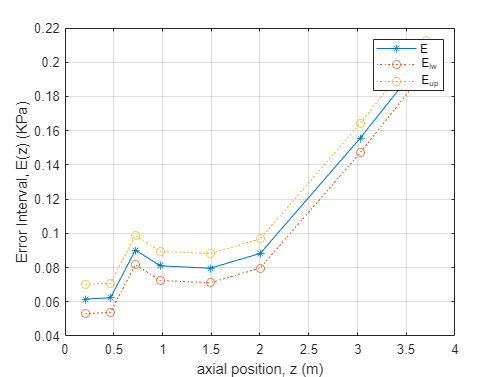

figure(1)
plot(z, E_b_z, '-*'), grid on, hold on
plot(z, E_b_z_lw, ':o')
plot(z, E_b_z_up, ':o')
legend('E','E_{lw}','E_{up}')
xlabel('axial position, z (m)')
ylabel('Error Interval, E(z) (KPa)')

### **Functions #### #### #### ####**

function y = std_ud(X)
    N = length(X);
    mu = sum(X)/N;  % mean finder
       
    sqsm = 0;       % square sum
   for i=1:1:length(X)
        sqsm = sqsm + (X(i) - mu)^2;
    end 
    
    y = sqrt(sqsm/(N-1));
end